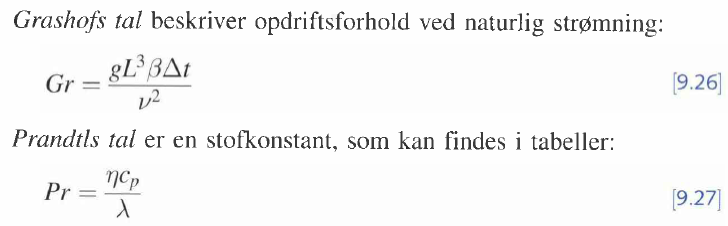

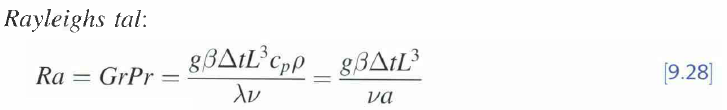

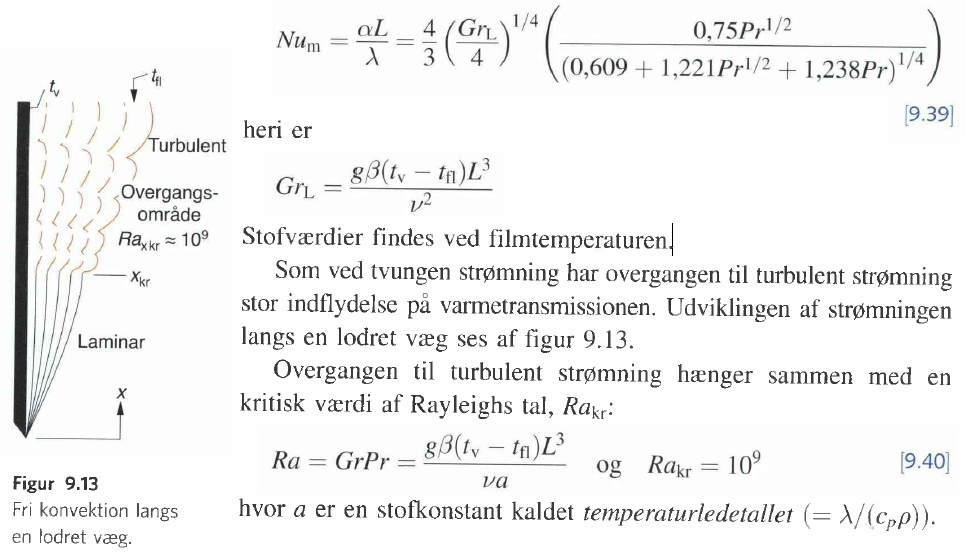

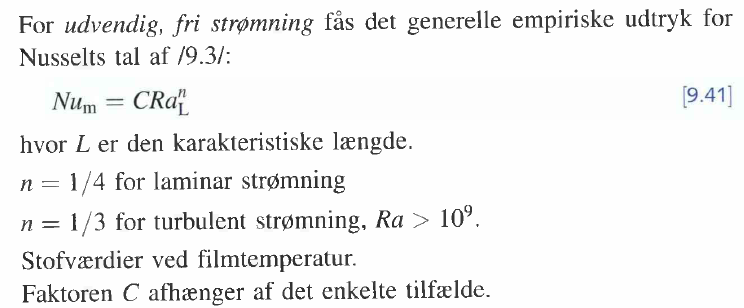

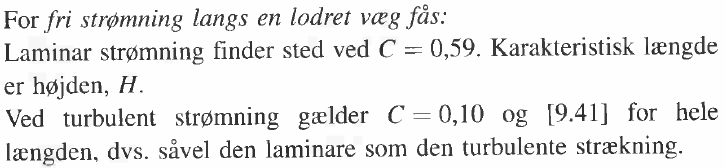

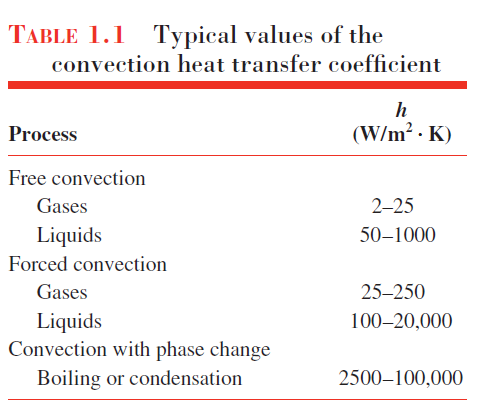

clear all
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% h = 10;
g = 9.82;
w_tot = 0.555; %højden af radiatoren
l_tot = 1.18

l_tot = 1.1800

k = 177; %konducteviteten for alu tabel A.1
N = 66; %antal finner per side
w = 0.465; %højden af findenen
L = 0.03; %længden af finnen
T =  0.0005; % tykkelsen af finnen

L_c = L + T/2

L_c = 0.0302

A_t_rad = w_tot * l_tot %arealet af radiatoren

A_t_rad = 0.6549

A_f = 2*w*L_c %finne arealet

A_f = 0.0281

A_b = w_tot*l_tot - w*T*N %arealet af basen

A_b = 0.6396

A_t = N*A_f + A_b %total areal finner

A_t = 2.4963

A_c = w*T

A_c = 2.3250e-04

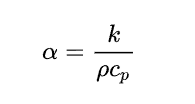

% A_vand =  w * N/2 * (8e-3 * 3e-3)
% P_vand = 1e5 * 1.4; % P_ambient = 101300
% 
% syms c
% c_vand = c;
% 
vand = 'Water';
T_ind = 47 + 273.15

T_ind = 320.1500

T_ud = 28 + 273.15

T_ud = 301.1500

% T_vand = (T_ind + T_ud)/2
% T_vand_s = T_vand
% T_vand_film = (T_vand + T_vand_s)/2
% 
% k_vand = CoolProp.PropsSI('L', 'P', P_ambient, 'T', T_vand_film, vand) %thermalConductivity
% 
% eta_vand = CoolProp.PropsSI('V', 'P', P_ambient, 'T', T_vand_film, vand)
% c_p_vand = CoolProp.PropsSI('Cpmass', 'P', P_ambient, 'T', T_vand_film, vand)
% rho = CoolProp.PropsSI('D', 'P', P_ambient, 'T', T_vand_film, vand) %Densitet
% nu_vand = eta_vand/rho
% Re = c_vand* L/nu_vand
% 
% 
% R_cond = 1/(k*A_vand)


For luft

fluid = 'Air'

fluid = 'Air'

CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure

T_avg = (T_ind + T_ud)/2 % - 273.15 %middel temperaturen af vandet

T_avg = 310.6500

T_luft = 20 +273.15

T_luft = 293.1500

T_v = T_avg % start gæt på væg temperaturen

T_v = 310.6500

syms h_luft
C = 0.59; % til Nussels tal for fri strømning langs en lodret væg

T_fluid = (T_v + T_luft)/2 % middel film temeperatur

T_fluid = 301.9000

mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid) %Dynamisk viscositet

mu = 1.8629e-05

rho = CoolProp.PropsSI('D', 'P', P, 'T', T_fluid, fluid) %Densitet

rho = 1.1696

nu = mu/rho

nu = 1.5928e-05

% nu = 15.06e-6; % ved 20 grad
k_luft = CoolProp.PropsSI('L', 'P', P, 'T', T_fluid, fluid) %thermalConductivity

k_luft = 0.0265

c_p_luft = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_fluid, fluid) %specificHeat_p

c_p_luft = 1.0064e+03

a = k_luft/(rho * c_p_luft) % temperaturledetallet m^2/s

a = 2.2534e-05

beta = 1/T_fluid %volumenudvidelseskoefficienten % [1/K]

beta = 0.0033



Gr = g * beta * (T_v - T_luft)*w^3/nu^2

Gr = 2.2559e+08

Pr = mu * c_p_luft / k_luft

Pr = 0.7068


Ra_test = g * beta * (T_v - T_luft)*w^3/(nu * a)

Ra_test = 1.5946e+08


Ra_L = Gr * Pr

Ra_L = 1.5946e+08

if Ra_L < 1e9
    n = 1/4;
else
    n = 1/3;
end


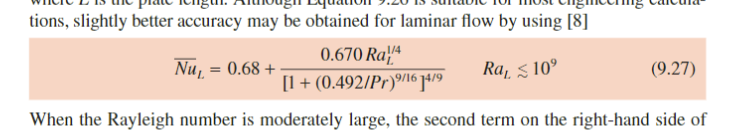

% Nu_m = C * Ra_L^n %fra den danske termo bog
Nu_m = 0.68 + (0.670 * Ra_L^(1/4))/(1 + (0.492/Pr)^(9/16))^(4/9) % eq 9.27

Nu_m = 58.4379

% Nu_eq = h_luft*L/k_luft = 4/3 * (Gr/4)^(1/4) * g*Pr

% h_eq = 0 == Nu_m/w * k_luft - h_luft


% h_luft = solve(h_eq, h_luft);
% h_luft = double(h_luft)

h_luft = Nu_m/w * k_luft

h_luft = 3.3335


%%%%%%%%%%%% kommet hertil

P_w = 2*w

P_w = 0.9300

m = sqrt(h_luft*P_w/(k*A_c))

m = 8.6795

eta_f = tanh(m*L_c) / (m*L_c) % eq (3.95)

eta_f = 0.9776

eta_0 = 1 - (N  * A_f) / A_t * (1 - eta_f) % (3.107) eller 3.110a med /C1

eta_0 = 0.9834

R_finner = 1/(eta_0 * h_luft * A_t)

R_finner = 0.1222


q_fin = (T_v - T_luft)/R_finner

q_fin = 143.2039

% q_2_sider_fin = q_fin*2

R_plade = 1/(h_luft * A_t_rad)

R_plade = 0.4581


% q_2_sider = q*2


Radiation

sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
epsilon = 0.9; % emmission factor

q_rad = epsilon * sigma * (T_v^4 - T_luft^4) * A_t_rad % = h_r * A_plate * (T_2 - T_sur) % 

q_rad = 64.4290


R_rad = (T_v - T_luft)/q_rad

R_rad = 0.2716


R_tot_plade = 1/(1/R_plade + 1 / R_rad)

R_tot_plade = 0.1705

q_plade = (T_v - T_luft)/R_tot_plade

q_plade = 102.6337


q_tot = (q_fin + q_plade)*2

q_tot = 491.6753

Vandstrømmen til radiatoren - energi ligning


$$\begin{array}{l}
q_m \cdot h_1 =q_m \cdot h_2 +q_{\mathrm{tot}} \\
q_m \left(h_1 -h_2 \right)=q_{\mathrm{tot}} \\
q_m =\frac{q_{\mathrm{tot}} }{\left(h_1 -h_2 \right)}\\
h=c_p \cdot T
\end{array}$$


P_vand = 1e5 * 1.4

P_vand = 140000

c_p_vand_ind = CoolProp.PropsSI('Cpmass', 'P', P_vand, 'T', T_ind, vand)

c_p_vand_ind = 4.1805e+03

c_p_vand_ud = CoolProp.PropsSI('Cpmass', 'P', P_vand, 'T', T_ud, vand)

c_p_vand_ud = 4.1802e+03


% h_1 = c_p_vand_ind * T_ind
h_1 = CoolProp.PropsSI('H', 'P', P_vand, 'T', T_ind, vand)

h_1 = 1.9691e+05


% h_2 = c_p_vand_ud * T_ud
h_2 = CoolProp.PropsSI('H', 'P', P_vand, 'T', T_ud, vand)

h_2 = 1.1750e+05


q_tot

q_tot = 491.6753

q_m = q_tot / (h_1 - h_2)

q_m = 0.0062